# Projeto - Eletromagnetismo e Ondulatória

## Modelando Antena Emissora

ant = spiralArchimedean('Turns', 5) % entre 3 e 6 voltas

ant =   spiralArchimedean with properties:

             NumArms: 2
               Turns: 5
         InnerRadius: 5.0000e-04
         OuterRadius: 0.0398
    WindingDirection: 'CCW'
                Tilt: 0
            TiltAxis: [1 0 0]
                Load: [1×1 lumpedElement]


ant.NumArms = 1; % número de braços (ramos)  = 1
ant.Tilt = 90; % Inclinação da antena plano 3D
ant.TiltAxis = "Y"

ant =   spiralArchimedean with properties:

             NumArms: 1
               Turns: 5
         InnerRadius: 5.0000e-04
         OuterRadius: 0.0398
    WindingDirection: 'CCW'
                Tilt: 90
            TiltAxis: 'Y'
                Load: [1×1 lumpedElement]


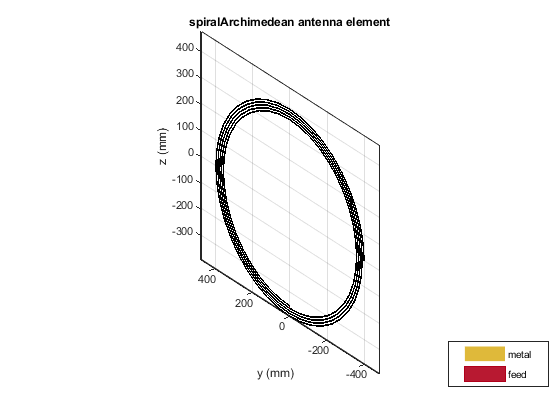

ant.OuterRadius = 40e-2; 
ant.InnerRadius = 35e-2;
show(ant)

## Impedância da Antena

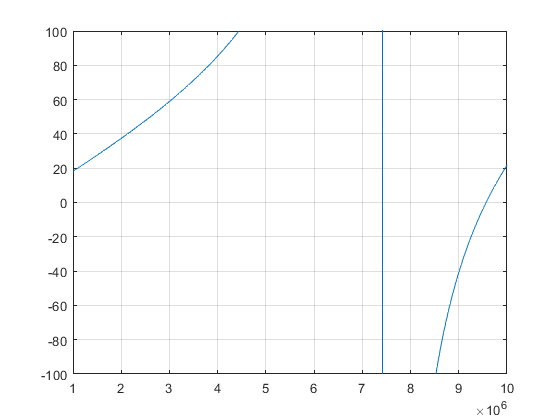

f = linspace(1e6, 1e7, 200);

impedancia = impedance(ant,f);
imaginario = imag(impedancia);
plot(f,imaginario)
ylim([-100, 100])
grid


% Impedância nula = f = 9547740
% Wc = 4437190

## Modelando Antena Receptora

ant2 = spiralArchimedean('Turns', 5) % entre 3 e 6 voltas

ant2 =   spiralArchimedean with properties:

             NumArms: 2
               Turns: 5
         InnerRadius: 5.0000e-04
         OuterRadius: 0.0398
    WindingDirection: 'CCW'
                Tilt: 0
            TiltAxis: [1 0 0]
                Load: [1×1 lumpedElement]


ant2.NumArms = 1; % número de braços (ramos)  = 1
ant2.Tilt = 90; % Inclinação da antena plano 3D
ant2.TiltAxis = "Y"

ant2 =   spiralArchimedean with properties:

             NumArms: 1
               Turns: 5
         InnerRadius: 5.0000e-04
         OuterRadius: 0.0398
    WindingDirection: 'CCW'
                Tilt: 90
            TiltAxis: 'Y'
                Load: [1×1 lumpedElement]


ant2.OuterRadius = 40e-2; 
ant2.InnerRadius = 35e-2;
show(ant2)

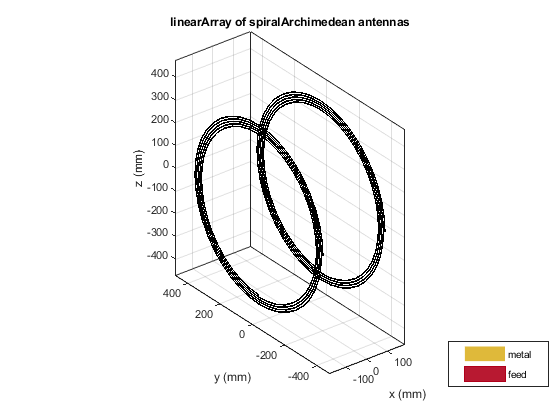



% Element Space
la = linearArray;
la.Element = [ant, ant2];
la.ElementSpacing = .3;
show(la);

## Simulando o Acoplamento

sd = sparameters(la, f)

sd =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [200×1 double]
     Parameters: [2×2×200 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


## Visualizando os Ganhos

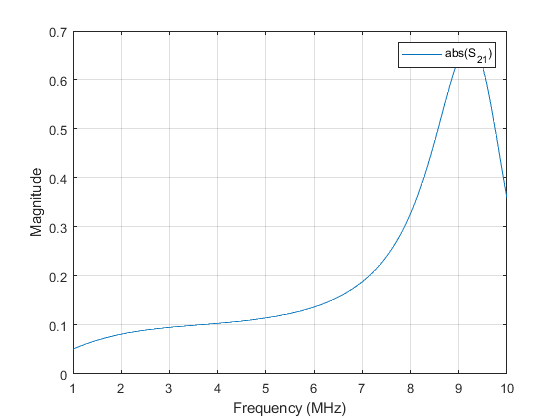

rfplot(sd,2,1,'abs')

Essa frequência é especial pois é a de ressonância (amplifica o ganho). A relação é a de que, a maior magnitude é aquela com frequência semelhante a de ressonância do gráfico de impedâncias, ou seja, o ponto em que a parte imaginária da impedância é zero.

#### Gráfico 3D

spacing = linspace(5e-2, 50e-2, 200);
la.ElementSpacing = spacing;

Error using em.ArrayProp/checkspacingdims
The Number of entries for Spacing should be 1 instead of 200

Error in em.ArrayProp/checkElementSpacing

Error in linearArray/set.ElementSpacing (line 138)
            checkElementSpacing(obj,propVal);

%sd_2 = sparameters(la, f)
%rfplot(sd_2,2,1,'abs')